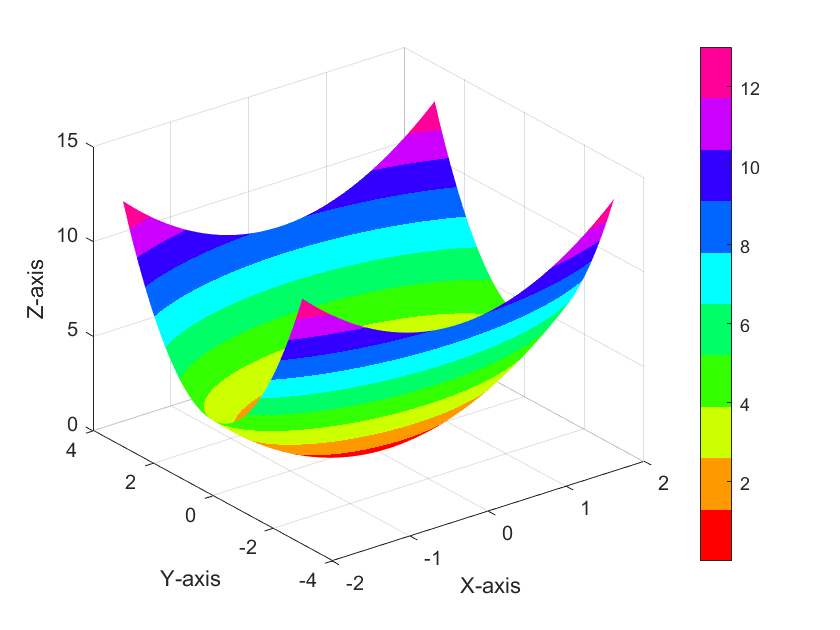

clear 
x = linspace(-2, 2);
y = linspace(-3, 3);
[X, Y] = meshgrid(x,y);
Z1 = X.^2 + Y.^2;

figure
surf(X,Y,Z1)
xlabel("X-axis")
ylabel("Y-axis")
zlabel("Z-axis")
shading interp
colormap(hsv(10))
colorbar

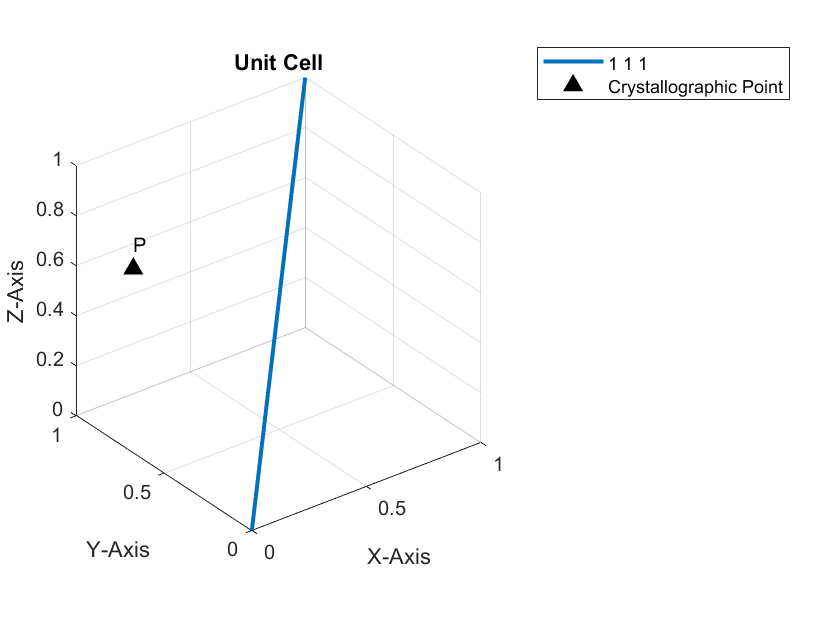



figure
a = [0, 1];
b = [0, 1];
c = [0, 1];
plot3(a,b,c,'LineWidth',2)
hold on
plot3(0.25, 1, 0.5, 'k^', 'MarkerSize',8,"MarkerFaceColor",'black')
text(0.25,1,0.6,"P")
legend("1 1 1","Crystallographic Point")
title("Unit Cell")
xlabel("X-Axis"); ylabel("Y-Axis"); zlabel("Z-Axis"); 
axis equal
grid on

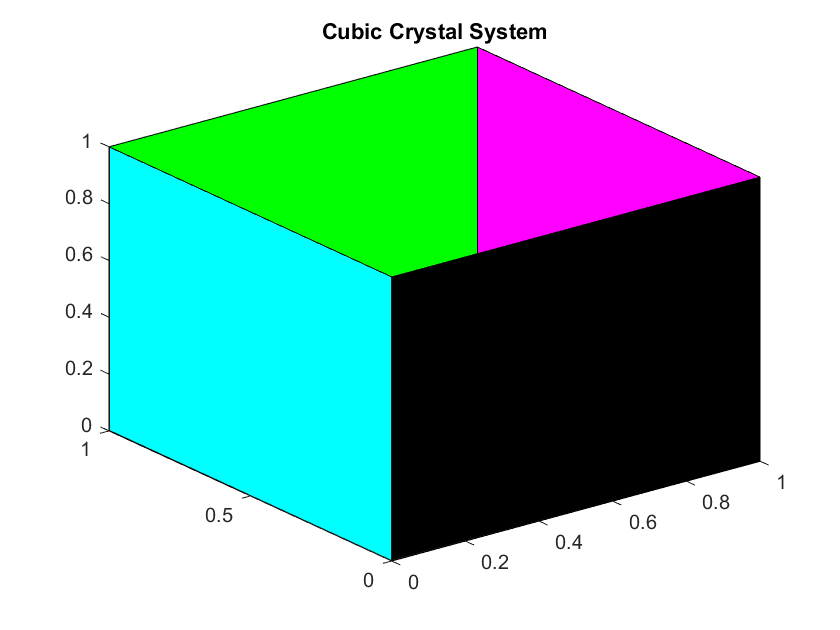


figure
x_cor = [0 1 1 0 0 1 1 0];
y_cor = [0 0 1 1 1 1 0 0];
z_cor = [1 1 1 1 0 0 0 0];
plot3(x_cor,y_cor,z_cor,'k')
patch([0 1 1 0],[0 0 1 1],[0 0 0 0],'blue')
% patch([0 1 1 0],[0 0 1 1],[1 1 1 1],'black')
patch([0 1 1 0],[0 0 0 0],[1 1 0 0], 'black')
patch([0 1 1 0],[1 1 1 1],[1 1 0 0],'green')
patch([1 1 1 1],[0 1 1 0],[1 1 0 0],'magenta')
patch([0 0 0 0],[0 0 1 1],[1 0 0 1],'cyan')
title('Cubic Crystal System')

Ploting a sphere

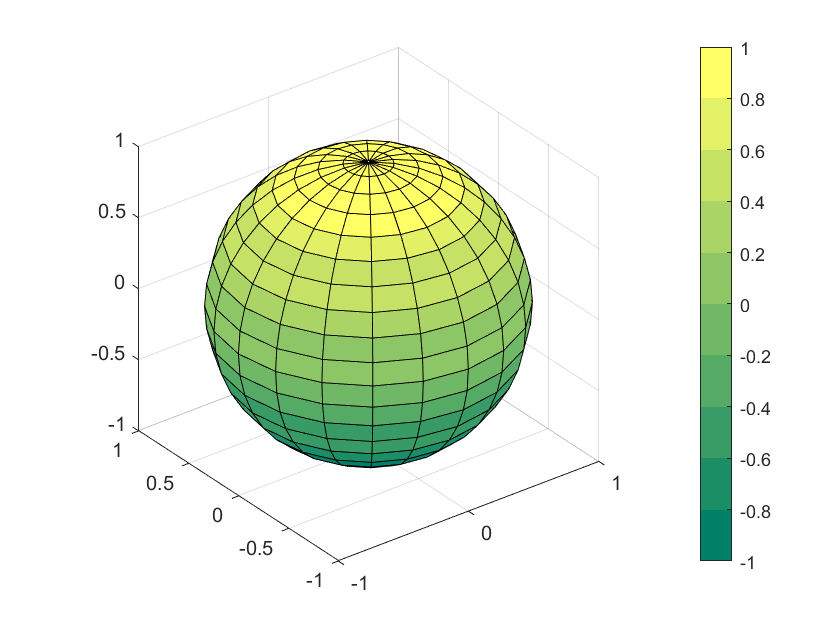

% Plots a unit sphere, with radius of 1 and center at (0,0,0)
sphere;
axis equal;
% Returns the coordinates of the unit sphere, but does not plot
% argument spheres the number of faces as 50-by-50 faces
[X,Y,Z] = sphere(50);
% modify the colormap
colormap(summer(10))
colorbar

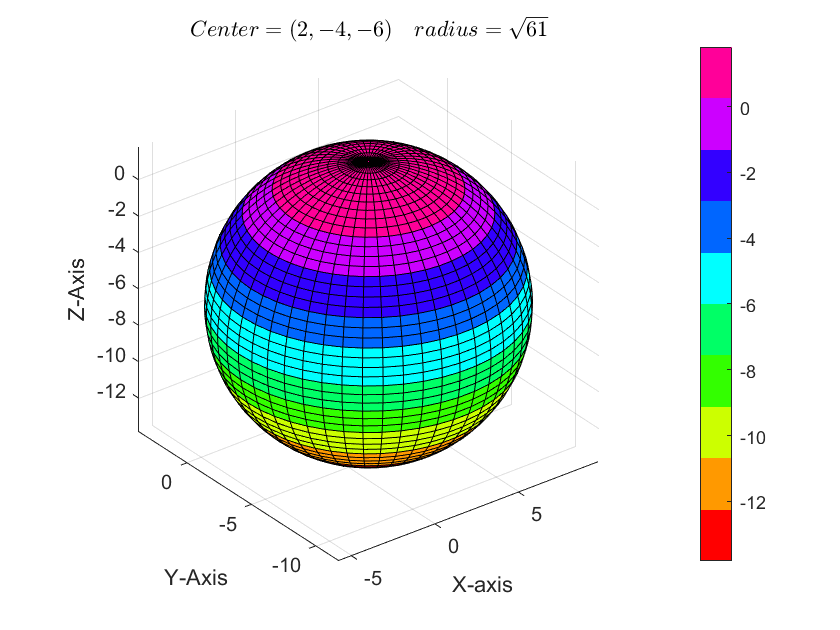


radius = sqrt(61);
% Multiply the respective x,y,z coordinates by the radius(since radius = 1) 
X2 = X * radius;
Y2 = Y * radius;
Z2 = Z * radius;

% To include the x,y,z coordinates, to define the center of the 
% sphere add or subtract them respectively.
% tiledlayout(1,2)
% ax1 = nexttile;
surf(X2+2,Y2-4 ,Z2-6)
colormap(hsv(10))
colorbar
title('$Center = (2, -4, -6) \quad radius = \sqrt{61}$','Interpreter',"latex")
xlabel('X-axis'); ylabel('Y-Axis'); zlabel('Z-Axis');
grid on
axis equal

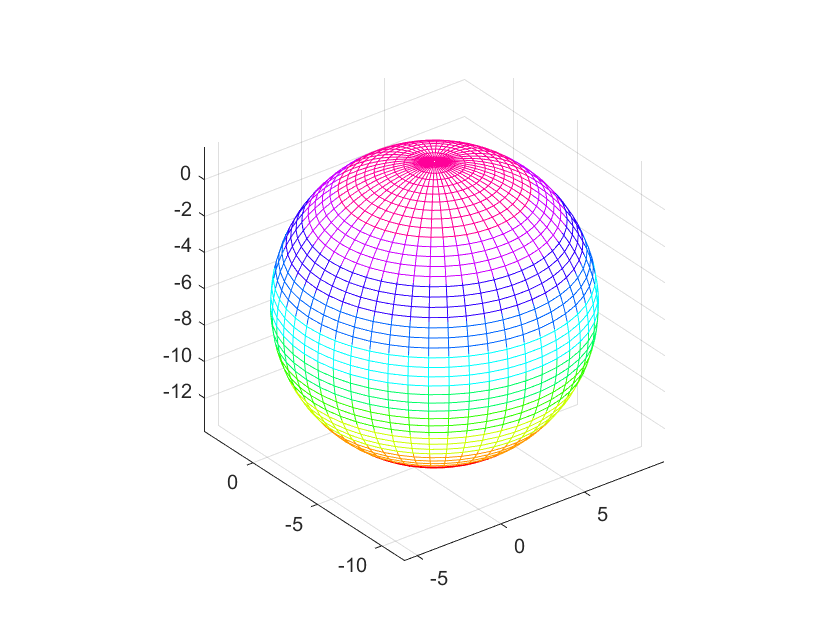


% or use the mesh function to plot the sphere
mesh(X2+2,Y2-4 ,Z2-6)
grid on
axis equal
shading interp

Plotting a cylinder

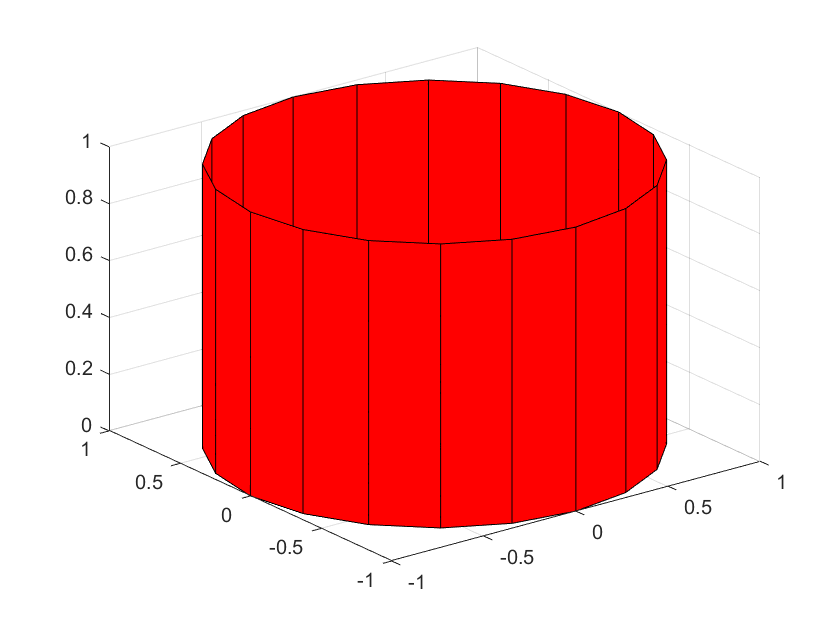

cylinder;

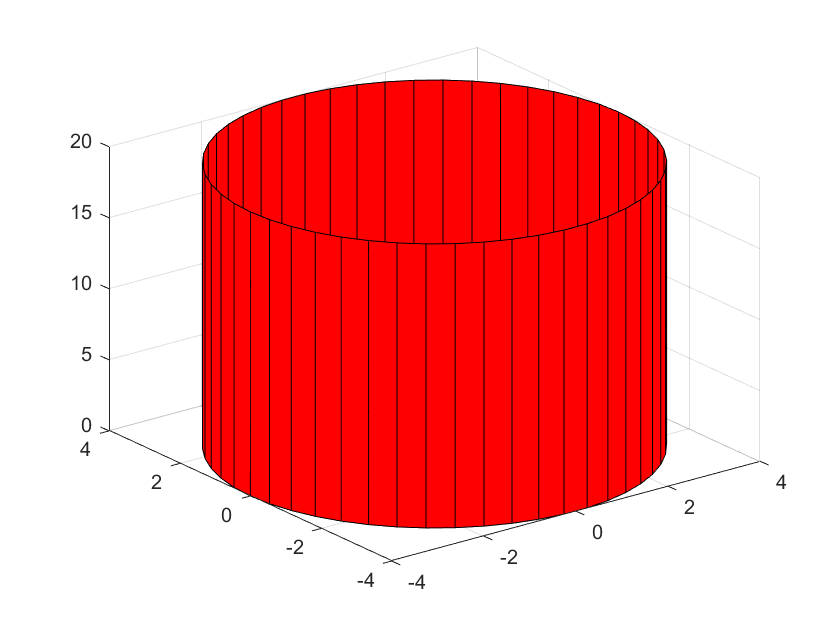

r = 4;
% first argument is the profile curve(radius), second is the number of
% points around the circumference
[X, Y, Z] = cylinder(r,50);
height = 20;
Z = Z * height;
surf(X,Y,Z)